# Training Unit 3: RLC Simulation

Fink Lucas / Teichtmeister Marcus, 15.10.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Task

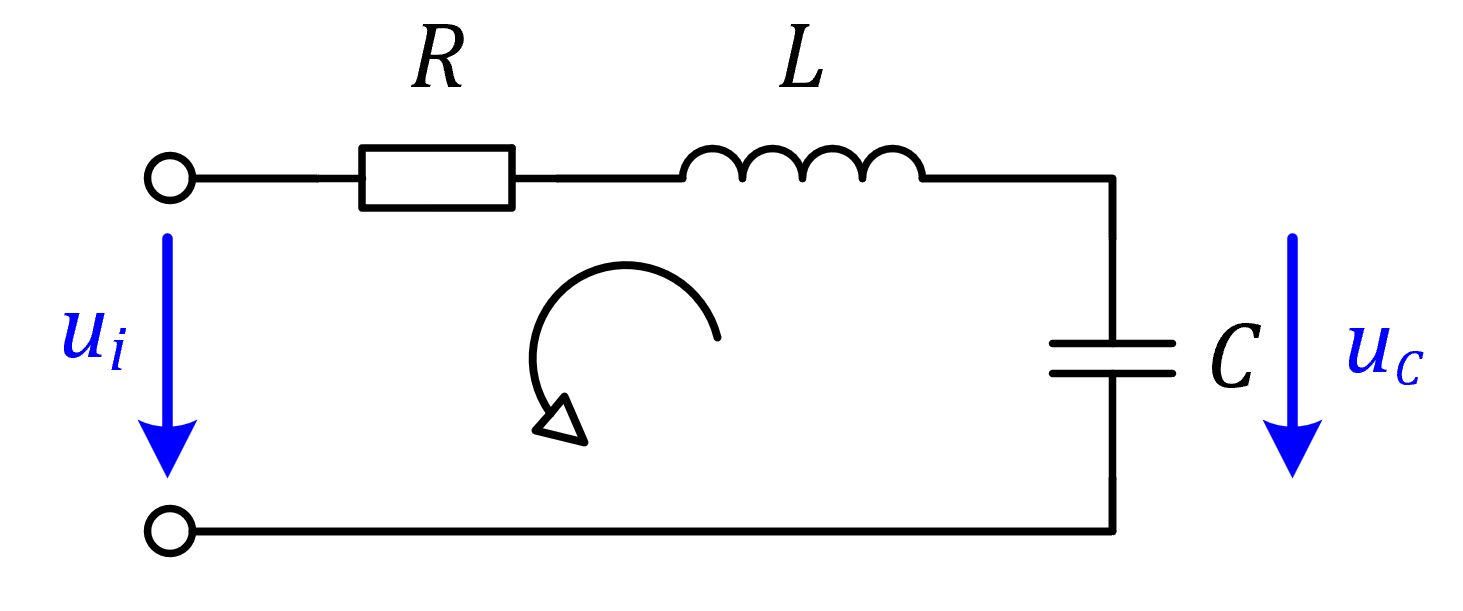

The voltage of the capacitor $u_c$ needs to be simulated using different methods:

- solving the ordinary differential equation on Simulink

- simulate the circuit on Simscape

- simulate the circuit on LTSpice

- solving it with its transfer function

## Deriving the differential equation of the RLC circuit

With the help of Kirchhoff's voltage law and the relationship between inductance / capacitance and current / voltage, it is possible to derive the needed ODE. It is also important to say, that the input voltage is a heaviside function, which has its step at 2 seconds and an amplitude of 3V.


$$\sum u=0\mathrm{V}:u_i -u_R -u_L -u_C =0\mathrm{V}$$


$i=C\;\frac{\mathrm{d}}{\mathrm{d}\mathrm{t}}u$ and $u=L\;\frac{\mathrm{d}}{\mathrm{d}\mathrm{t}}i$

The voltage of the capacitor is needed, therefore only the input voltage and the capacitor voltage have to be in the ODE. According to the schematic all elements are in series, hence only one current exists and can be described with the capacitance.

                    
$$i=C\frac{\;\mathrm{d}\;u_C }{\mathrm{d}\;\mathrm{t}\;}$$


Voltage of resistor and inductor can also be described with the current:

                    $u_R =i\cdot R=R\;C\frac{{\mathrm{d}\;u}_C \;}{\textrm{dt}}$ and $u_L =L\frac{\;\mathrm{d}\;i}{\textrm{dt}}=L\;\frac{\mathrm{d}}{\textrm{dt}}C\;\frac{\mathrm{d}\;u_C }{\textrm{dt}}=L\;C\;\frac{{\mathrm{d}}^2 \;u_C }{{\textrm{dt}}^2 }$

                    
$$u_i -u_C -R\;C\frac{\;{\mathrm{d}\;u}_C }{\textrm{dt}}-L\;C\frac{\;{\mathrm{d}}^2 \;u_C }{\;\textrm{dt}}=0\mathrm{V}$$


Now it is possible to either derive the explicite expression of the ODE or its transfer function.

    Explicite Expression:

                    
$$\frac{{\mathrm{d}}^{2\;} u_C }{{\textrm{dt}}^2 }=\frac{1}{L\;C}\;u_i -\frac{1}{L\;C}\;u_C -\frac{R}{L}\frac{\;\mathrm{d}\;u_C }{\textrm{dt}}=\frac{1}{L\;C}\;\left(u_i -u_C -R\;C\frac{\;\mathrm{d}\;u_C }{\textrm{dt}}\right)$$


    Transfer Function:

                    
$$\mathcal{L}\;\left\lbrace u_i \right\rbrace =\mathcal{L}\;\left\lbrace u_C +R\;C\frac{\;{\mathrm{d}\;u}_C }{\textrm{dt}}+L\;C\frac{\;{\mathrm{d}}^2 \;u_C }{\;\textrm{dt}}\right\rbrace$$


                    
$$\breve{\;u_i } \frac{\;e^{-2s} }{s}=\breve{\;u_C } +R\;C\;\left(\breve{\;s\;u_C } -u_C \left(0\right)\right)+L\;C\;\left(s^2 \;\breve{\;u_C } -s\;u_C \left(0\right)-\dot{\;u_C } \left(0\right)\right)$$


                    Since the initial values are 0, the equation can be rewritten as:

                    
$$\breve{\;u_i } \frac{\;e^{-2s} }{s}=\breve{\;u_C } +s\;R\;C\;\breve{\;u_C } +s^2 \;L\;C\;\breve{\;u_C } =\breve{\;u_C } \left(1+\textrm{sRC}+s^2 \textrm{LC}\right)$$


                    
$$G\left(s\right)=\frac{\breve{\;u_C } }{\breve{\;u_i } }=\frac{e^{-2s} }{s+s^2 \textrm{RC}+s^3 \textrm{LC}}$$


                    For Simulink it is sufficient to type the delay into the step block and the term $\frac{e^{-2s} }{s}$ is not needed in the transfer function block. 

### Simulation

The graphic should start before and continue until a defined end time

End time for graphics

Sim.t_plot_end = 10;

Delay before the step

Sim.t_step = 2;

End time of the simulation

Sim.t_end = Sim.t_plot_end + Sim.t_step;

Parameters

RLC.u_i = 3;
RLC.R = 56000;
RLC.L = 100e-6;
RLC.C = 10e-6;

Importing LTspice Data

%% read LTSpice-Data from file

filename = './LTSpice/RLC_Serial.txt';

% load a table from txt data
ltspice_data = readtable(filename, 'Delimiter', '\t', 'ReadVariableNames', true);

% Simplify column names (no spaces for MATLAB compatibility)
ltspice_data.Properties.VariableNames = {'Time_s', 'u_c_V', 'u_i_V'};

% Time in seconds as duration
ltspice_data.Time_s = seconds(ltspice_data.Time_s);

% Replace NaN / Inf in signals
ltspice_data.u_c_V(~isfinite(ltspice_data.u_c_V)) = 3;
ltspice_data.u_i_V(~isfinite(ltspice_data.u_i_V)) = 3;


LTSpice_uc = [seconds(ltspice_data.Time_s), ltspice_data.u_c_V];

open('RLC_Simulation.slx')

sim('RLC_Simulation.slx')

#### Voltage over the Capacitor

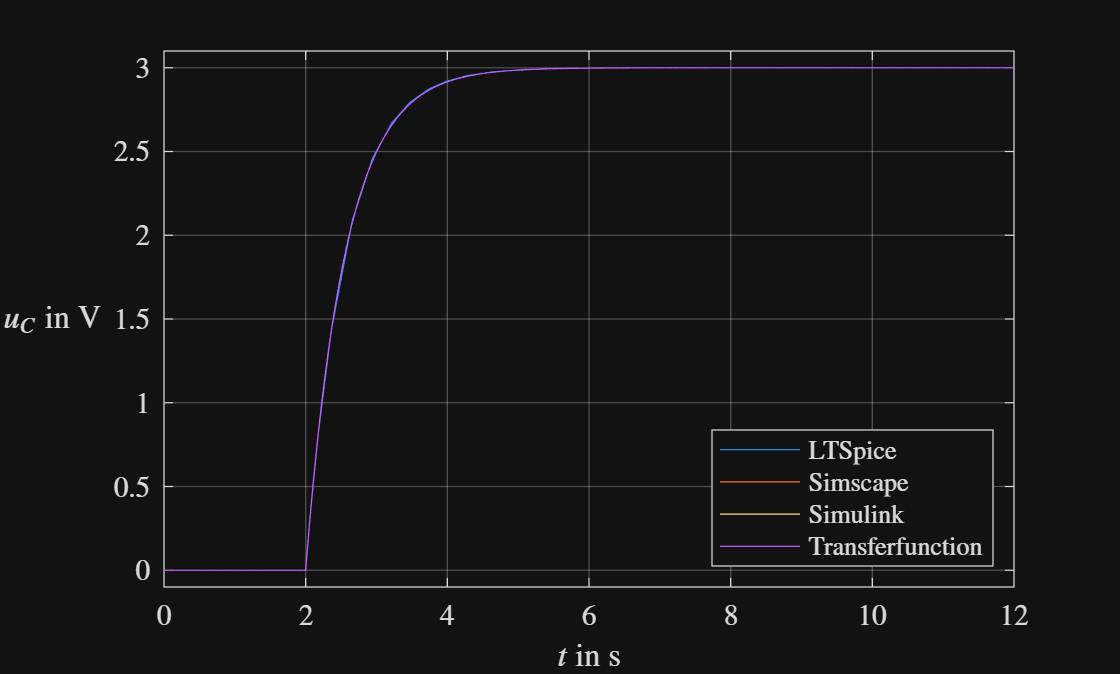

figure

tiledlayout(1, 1)

plot(RLC_SIM.get('uc_ltspice').Values.Time, RLC_SIM.get("uc_ltspice").Values.Data, 'DisplayName','LTSpice')
hold on
plot(RLC_SIM.get('uc_simscape').Values.Time, RLC_SIM.get("uc_simscape").Values.Data, 'DisplayName','Simscape')
plot(RLC_SIM.get('uc_simulink').Values.Time, RLC_SIM.get("uc_simulink").Values.Data, 'DisplayName','Simulink')
plot(RLC_SIM.get('uc_transferfunction').Values.Time, RLC_SIM.get("uc_transferfunction").Values.Data,'DisplayName','Transferfunction')
grid('on')
axis([0, Sim.t_end, -0.1, 3.1])
ylabel('$u_C$ in V')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

xlabel('$t$ in s')
legend('Location', 'southeast')

The figure shows, that all methods lead to the same result.

#### Current

In order to calculate the current out of the capacitor voltage, the derivation of the voltage multiply by its capacitance is needed. In other words, the output of Simulink and Transferfunction needs two extra blocks: first the derivative and then gain.

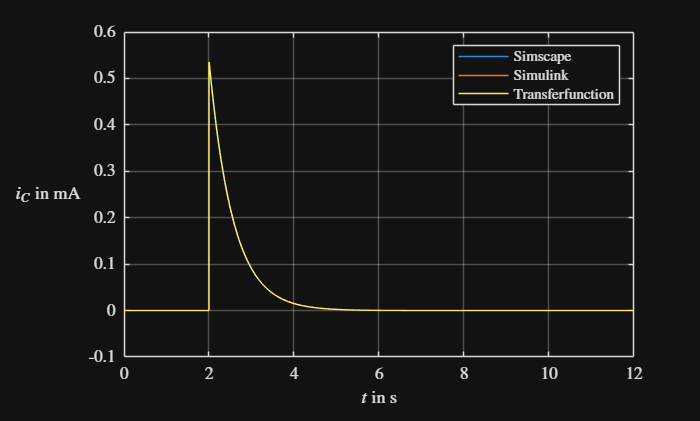

figure

tiledlayout(1, 1)

pl1 = nexttile;
plot(RLC_SIM.get('ic_simscape').Values.Time, RLC_SIM.get("ic_simscape").Values.Data .*10e3, 'DisplayName','Simscape')
hold on
plot(RLC_SIM.get('ic_simulink').Values.Time, RLC_SIM.get("ic_simulink").Values.Data .*10e3, 'DisplayName','Simulink')
plot(RLC_SIM.get('ic_transferfunction').Values.Time, RLC_SIM.get("ic_transferfunction").Values.Data .*10e3,'DisplayName','Transferfunction')
grid('on')
ylabel('$i_C$ in mA')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

xlabel('$t$ in s')
legend('Location', 'northeast')

The figure again shows, that all methods lead to the same result.